↓この極零配置をベースにp1,p2,z1,z2の実部の大小関係が変わったらオーバシュート有無はどうなるか確認

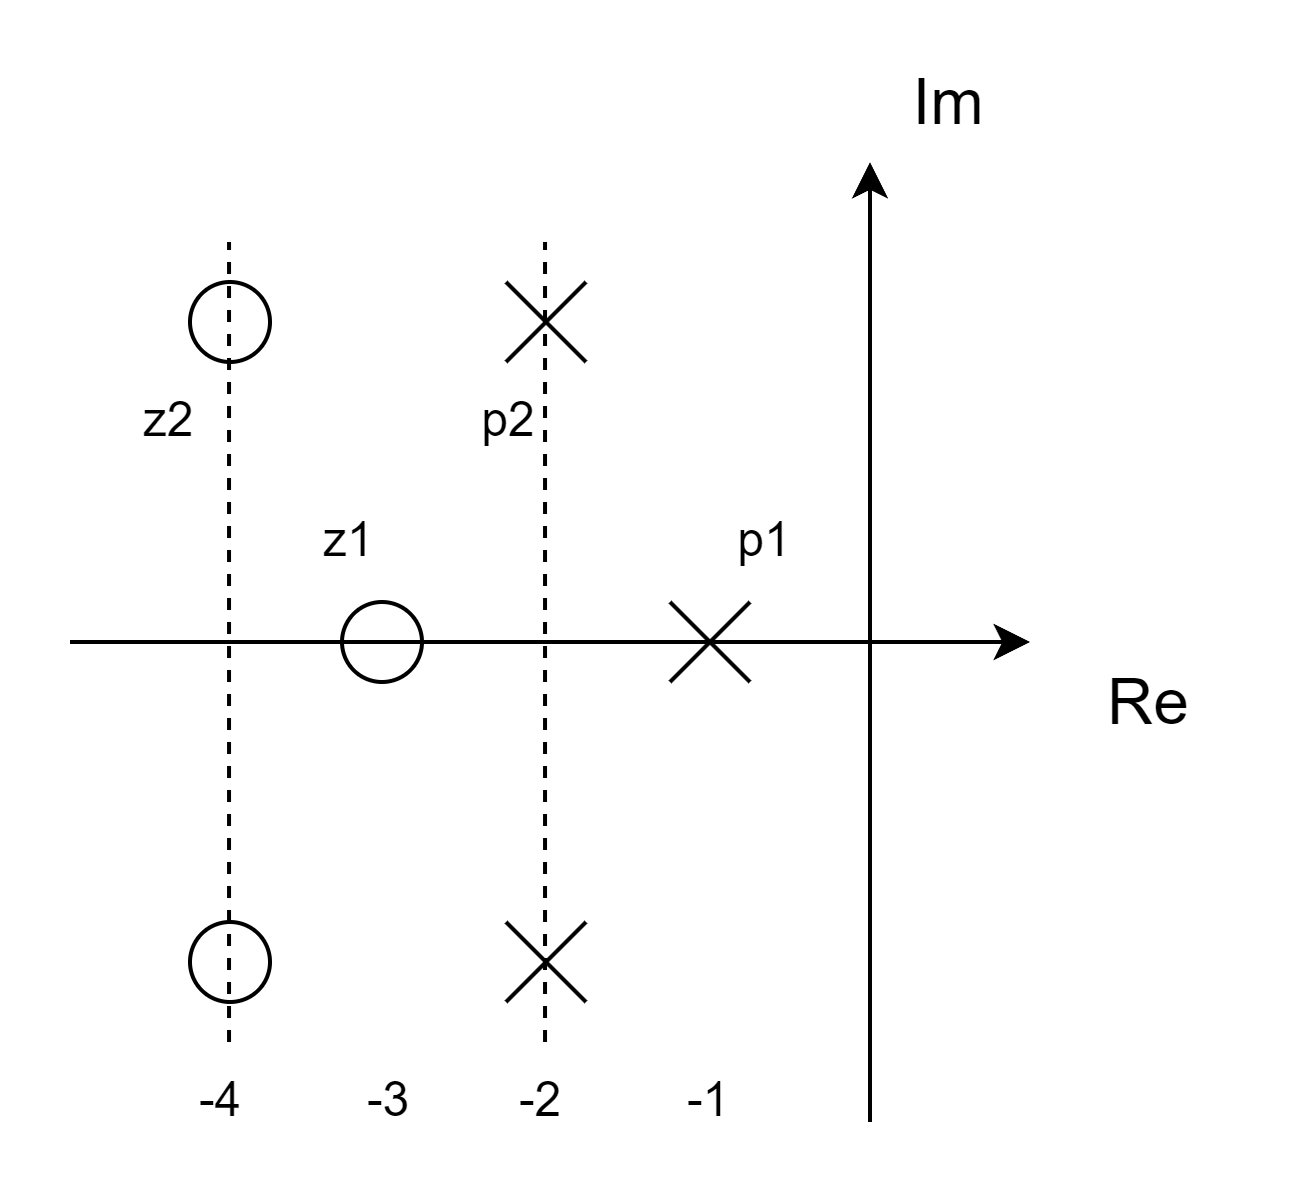

ひとつの例

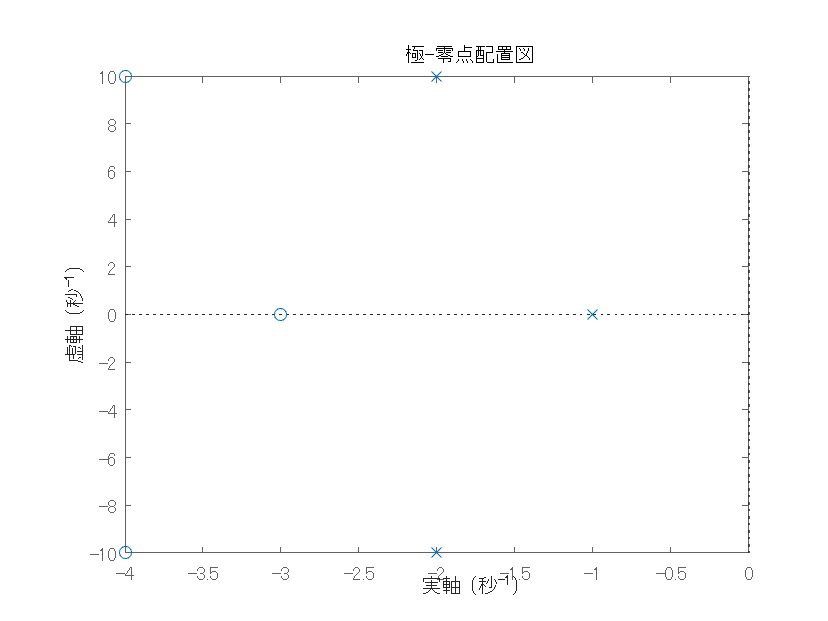

clear;

impos = -10; % 虚部は適当に大きめにしておく

p1 = -1;
p2 = -2 + impos*[1i -1i];
z1 = -3;
z2 = -4 + impos*[1i -1i];

tf = zpk([z1 z2],[p1 p2],1);
pzmap(tf)

極ーゼロの位置を変えていった場合

pos_pattern = [1, 2, 3, 4];

pos_perm = -perms(pos_pattern);
legends = cell(length(pos_perm),1);

color_group = 4;
[cptn,cptn_idx]= setColorPtn([],length(pos_perm),color_group,2/3);
colororder(cptn);


for pos = 1:length(pos_perm)
    p1 = pos_perm(pos,1);
    p2 = pos_perm(pos,2) + impos*[1i -1i];
    z1 = pos_perm(pos,3);
    z2 = pos_perm(pos,4) + impos*[1i -1i];
    
    all_poles = [p1, p2];
    all_zeros = [z1, z2];

    % 定常ゲインを1に調整
    numerator = prod(-all_zeros);
    denominator = prod(-all_poles);
    gain_adjusted = denominator / numerator;

    tf = zpk([z1 z2],[p1 p2],gain_adjusted);
    [yout, tout] = step(tf,10);
    plt = plot(tout,yout);
    legends{pos} = "p1=" + string(p1) + ", p2=" + string(real(p2(1))) + ", z1=" + string(z1) + ", z2=" + string(real(z2(1)));
    
    % 1+εを超えなかったものの表示
    if(max(yout) < 1+0.0001)
        display(legends{pos});
    end

    % データヒントの追加
    plt.DataTipTemplate.DataTipRows(end+1).Label = legends{pos};
    hold on;
end

    "p1=-2, p2=-4, z1=-3, z2=-1"

    "p1=-2, p2=-3, z1=-4, z2=-1"

    "p1=-1, p2=-4, z1=-3, z2=-2"

    "p1=-1, p2=-4, z1=-2, z2=-3"

    "p1=-1, p2=-3, z1=-4, z2=-2"

    "p1=-1, p2=-3, z1=-2, z2=-4"

    "p1=-1, p2=-2, z1=-4, z2=-3"

    "p1=-1, p2=-2, z1=-3, z2=-4"



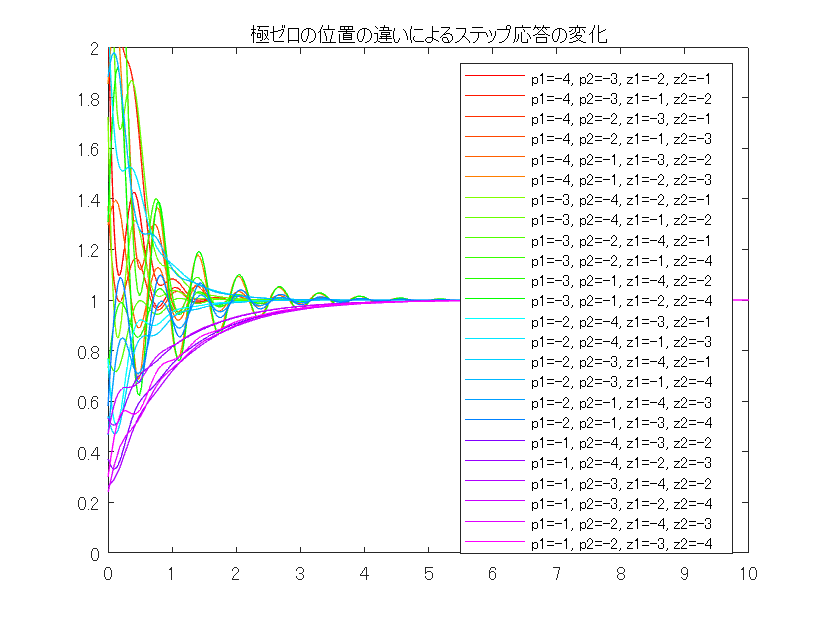

ylim([0 2])
lgd = legend(legends);
lgd.ItemHitFcn = @hitcallback_ex1; % グラフ表示/非表示切り替え用のコールバック関数登録
title('極ゼロの位置の違いによるステップ応答の変化')
hold off;

`凡例クリックでグラフ表示/非表示切り替え`

function hitcallback_ex1(src,evnt)

    if strcmp(evnt.Peer.Visible,'on')
        evnt.Peer.Visible = 'off';
    else 
        evnt.Peer.Visible = 'on';
    end

end